clc
clear

## input

miu_0 = 4 * pi * (1e-7);
a = 0.1;
L = 0.4;
gama = 90;
theta = 0;
phi = -5;
b_0 = 55000;
I = 70;
D = 3.5;
X = 0:1:50;
Y = 0:1:50;
Z = 0;
x_0 = 25;
y_0 = 25;
z_0 = 1.5;

phi = phi*(pi/180);
gama = gama*(pi/180);
theta = theta*(pi/180);
D = D*(pi/180);
I = I*(pi/180);
b_0 = b_0 .* [cos(I)*cos(D);cos(I)*sin(D);sin(I)];

## 计算体积和横纵轴比

e = L/a;%a < L
V = (4 * pi * L*a^2)/3;

## 计算欧拉旋转角

A = [cos(gama)*cos(phi),-cos(gama)*sin(phi),-sin(gama)
    sin(theta)*sin(gama)*cos(phi)+cos(theta)*sin(phi),-sin(theta)*sin(gama)*sin(phi)+cos(theta)*sin(phi),sin(theta)*cos(gama)
    cos(theta)*sin(gama)*cos(phi)-sin(theta)*sin(phi),-cos(theta)*sin(gama)*sin(phi)-sin(theta)*cos(gama),cos(theta)*cos(gama)];

## 计算有效磁化率矩阵

E = log(e - sqrt(e^2 - 1))/sqrt(e^2 - 1);
alpha_1 = (e * (e + E))/(e ^ 2 - 1);
alpha_3 = (-2 * e * (e^(-1) + E))./(e^2 - 1);
alpha_2 = (e * (e + E))/(e^2 - 1);
X_1 = 2/alpha_1;
X_2 = 2/alpha_2;
X_3 = 2/alpha_3;

v = [X_1 X_2 X_3];
X_d = diag(v);

## 计算总磁偶极矩

m_i = (V./miu_0) * A' * X_d * A * b_0;

m = m_i;

[X_0,Y_0]=meshgrid(X,Y);
miu_0 = 4 * pi * 10 ^ (-7);
R=cell(length(X_0),length(Y_0));

igrf1 = [cos(I)*cos(D);cos(I)*sin(D);sin(I)];
igrf = cell(length(X_0),length(X_0));



m1 = cell(length(X_0),length(Y_0));
for i=1:length(X_0)
    for j=1:length(Y_0)
        igrf{i,j} = igrf1;
        m1{i,j} = m;
        R{i,j}=[X_0(i,j)-x_0;Y_0(i,j)-y_0;Z-z_0];
        RR(i,j) = norm(R{i,j});
        temp1(i,j) = miu_0./(4 * pi * RR(i,j) ^ 3);
        temp2(i,j) = 3./RR(i,j).^2;
        temp3(i,j) = dot(R{i,j},m1{i,j});
        temp4{i,j} = temp3(i,j) * R{i,j};
        temp5{i,j} = temp2(i,j) * temp4{i,j} - m1{i,j};
        b{i,j} = temp1(i,j).*temp5{i,j};

        %F1{i,j} = igrf{i,j}.*b{i,j};
        %T(i,j)=norm(F1{i,j});
        %F(i,j) = dot(igrf{i,j},b{i,j});
        %T(i,j) = F(i,j);
        F1(i,j) = igrf{i,j}'*b{i,j};
        %
        %             if F1{i,j}(3)>0
        %                 T1(i,j)=norm(F1{i,j});
        %             else
        %                 T1(i,j)=-norm(F1{i,j});
        %         end
    end
end
%T_noise = awgn(F1,2);
figure(1)
% contourf(F1,30);
imagesc(F1)

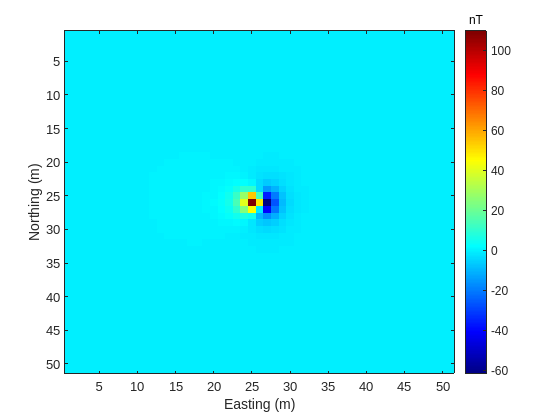

colorbar
colormap('jet');
xlabel('Easting (m)');
ylabel('Northing (m)');
h=colorbar;
set(get(h,'Title'),'string','nT');

figure(2)
plot(T_noise(32,:));

函数或变量 'T_noise' 无法识别。


%caxis([-40 100]);
% save('F1.mat','F1')